# Exercises 7.1

2.The values of a nodal variableuat the five nodes of a 1D element are shown in the table below. Plot theufield along theelement by using shape functions.

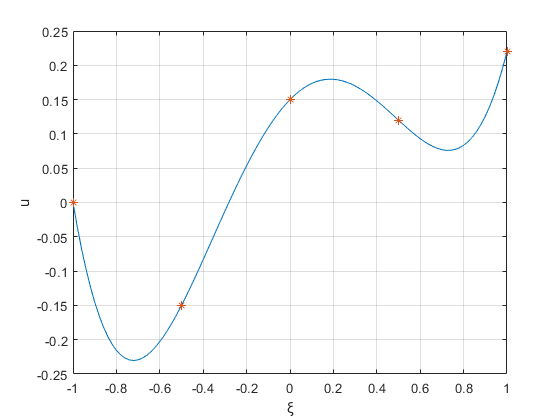

n = 101;
xi = linspace (-1, 1, n);      
u = [0.00; 0.22; -0.15; 0.12; 0.15];               
for num = 1:n
    N = shape_form_1d(xi(num));
    U(num,1) = N * u;
end
figure
plot(xi,U,[-1,1,-1/2,1/2,0],u,'*')
grid;
xlabel ("ξ");
ylabel ("u");

function N = shape_form_1d(xi)
N = [
1/6*(    xi -  xi^2 - 4*xi^3 + 4*xi^4);   % N1    
1/6*(-   xi -  xi^2 + 4*xi^3 + 4*xi^4);   % N2
1/3*(-4*xi + 8*xi^2 + 4*xi^3 - 8*xi^4);   % N3
1/3*( 4*xi + 8*xi^2 - 4*xi^3 - 8*xi^4);   % N4
(1         - 5*xi^2          + 4*xi^4)    % N5
]';           
end